## FRKSKIA001 and CLRCAM007 ES3 

### Prac 2

#### Prac 2.2: Parallel Processing in MATLAB 

% Create parallel pools
delete(gcp('nocreate'));

Parallel pool using the 'Processes' profile is shutting down.


p = parpool('Processes', 4);

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.


2.2.(a) This short task involves implementing the easy Bubble sort routine, just using looping, don’t attempt any parallelization. First implement Bubble sort, in the regular fashion, by using a nested for loop. A good explanation is given at: https://medium.com/codex/bubble-sorthow-it-works-psuedocode-and-c-python-implementationc45306d44827. Apply sorting to a 100x100 matrix of random numbers, you just use rand for generating random floats in the range (0,1). Sort the columns from minimum value to maximum value, like the MATLAB sort command does. i.ew. you will need another for loop for go through sorting each column of the matrix one column at a time. (NOTE: obviously not using the built in sort function). [10 marks]

Creating a bubble sort function look at BubbleSort

Testing the Bubble sort function

X=rand(100,100)

X =     0.0348    0.6538    0.2253    0.5300    0.0088    0.7572    0.9479    0.6097    0.1032    0.7091    0.6656    0.3514    0.9865    0.2628    0.2837    0.5402    0.4903    0.6636    0.9704    0.0199    0.9763    0.3410    0.6271    0.4197    0.8525    0.4507    0.4253    0.1731    0.2351    0.8387    0.6912    0.3450    0.2540    0.5699    0.3709    0.9140    0.6509    0.1746    0.5005    0.1097    0.1218    0.4103    0.9503    0.8708    0.4540    0.3566    0.5181    0.9260    0.7358    0.6972
    0.3879    0.4365    0.1983    0.6006    0.1711    0.7398    0.9163    0.1440    0.3309    0.0164    0.8678    0.4843    0.9771    0.1698    0.5127    0.6425    0.8241    0.5276    0.9485    0.2428    0.2268    0.2011    0.3583    0.5761    0.0237    0.1143    0.5869    0.1446    0.1176    0.3900    0.9347    0.9652    0.3522    0.6224    0.7414    0.1148    0.4336    0.9372    0.0212    0.6481    0.9783    0.6618    0.3867    0.1370    0.7207    0.0967    0.6058    0.1137    0.8111    0


for i = 1:100 
  X(:,i) = BubbleSort(X(:,i));
end 

2.2.(b) How does the built-in sort function compare in run time to your sequential sort implementation? Test, at least, for square matrixes of sizes 100, 200, 500, 1000, 10000. [5 marks]

% Initialize the cell array
testsizes = [100; 200; 500; 1000; 10000];
timetaken = cell(1+length(testsizes),4);
timetaken(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken
for i = 2:size(timetaken,1)
    % Call the timetest function with the value in the first column of the i-th row
    [timeBubble, timeInbuilt] = timetest(timetaken{i,1});
    timetaken{i,2} = timeBubble;
    timetaken{i,3} = timeInbuilt;
    % Calculate speed up
    timetaken{i,4} = timeBubble/timeInbuilt;
end

Y =     0.9914    0.8978    0.1452    0.2384    0.4963    0.7926    0.5168    0.1158    0.6360    0.9877    0.8360    0.0547    0.8579    0.3228    0.4073    0.3801    0.8128    0.1512    0.4897    0.2861    0.7371    0.8598    0.9646    0.3133    0.7769    0.2096    0.2251    0.5029    0.9355    0.3313    0.6557    0.5158    0.6180    0.0372    0.5875    0.2817    0.4937    0.2877    0.2488    0.5439    0.5590    0.2492    0.8716    0.3071    0.1330    0.7359    0.5374    0.8035    0.0402    0.3359
    0.5960    0.7849    0.5889    0.1386    0.4018    0.7407    0.8526    0.7161    0.5933    0.7611    0.5518    0.3195    0.7096    0.4524    0.0371    0.0147    0.9911    0.6843    0.8187    0.5073    0.7094    0.6314    0.4039    0.5097    0.4060    0.2279    0.0586    0.4741    0.2294    0.5285    0.9428    0.0179    0.0488    0.4701    0.7120    0.9568    0.9491    0.1609    0.0336    0.9284    0.3479    0.6954    0.9200    0.3018    0.8985    0.9973    0.6959    0.7483    0.7570    0

    "Time tacken by the bubble sort function was 0.0044608 s. Time tacken by the inbuilt sort function was: 0.0014654 s."



Y =     0.8661    0.7110    0.7237    0.2908    0.3474    0.4003    0.5029    0.9236    0.5900    0.4946    0.1290    0.9778    0.8363    0.8067    0.2584    0.5558    0.8397    0.6118    0.5317    0.0522    0.4951    0.3732    0.4750    0.4034    0.5359    0.0777    0.9150    0.1946    0.3879    0.7657    0.1539    0.1604    0.5148    0.8619    0.2401    0.6953    0.2923    0.8279    0.0891    0.9355    0.1484    0.0657    0.6690    0.5780    0.8012    0.0693    0.0639    0.6923    0.5739    0.8145
    0.5209    0.3282    0.4925    0.1036    0.2335    0.5244    0.1843    0.2699    0.9348    0.5720    0.2427    0.1610    0.1585    0.5593    0.1315    0.2884    0.7221    0.0616    0.6759    0.0377    0.2674    0.9734    0.7766    0.0363    0.6323    0.8210    0.1717    0.7152    0.7283    0.6715    0.1002    0.5834    0.7248    0.5803    0.1714    0.6570    0.6940    0.8720    0.8915    0.6322    0.3862    0.7700    0.5423    0.3104    0.7276    0.5266    0.2798    0.6154    0.2311    0

    "Time tacken by the bubble sort function was 0.017377 s. Time tacken by the inbuilt sort function was: 0.001483 s."



Y =     0.2135    0.4665    0.3882    0.6423    0.3166    0.6151    0.9520    0.2805    0.2384    0.2971    0.4074    0.0442    0.5002    0.8036    0.9440    0.1600    0.9434    0.1893    0.0685    0.5020    0.1832    0.6901    0.5614    0.3975    0.0506    0.8411    0.6221    0.7731    0.1963    0.2330    0.9239    0.8488    0.6113    0.1323    0.5502    0.5385    0.4230    0.5634    0.7236    0.1288    0.9002    0.0344    0.0538    0.0891    0.5005    0.1491    0.8946    0.5024    0.7790    0.5094
    0.2800    0.3076    0.4264    0.2872    0.1514    0.4107    0.0381    0.6037    0.5109    0.7182    0.0145    0.2503    0.6634    0.0564    0.7763    0.8224    0.9303    0.2877    0.0840    0.6102    0.2511    0.6580    0.2384    0.4610    0.8860    0.5437    0.5866    0.7418    0.7281    0.3728    0.9326    0.8128    0.4606    0.5395    0.2613    0.4151    0.5037    0.1648    0.6830    0.3852    0.1069    0.3511    0.7962    0.7146    0.5043    0.1326    0.0889    0.9208    0.0167    0

    "Time tacken by the bubble sort function was 0.18868 s. Time tacken by the inbuilt sort function was: 0.0090365 s."



Y =     0.1101    0.9027    0.5456    0.0230    0.8464    0.1116    0.1810    0.4083    0.7796    0.1132    0.6795    0.9619    0.5020    0.9693    0.1613    0.2006    0.4245    0.7859    0.5031    0.0817    0.1056    0.1897    0.5622    0.9639    0.1715    0.2506    0.7225    0.6198    0.2268    0.5146    0.0057    0.5069    0.2743    0.7051    0.8035    0.1603    0.0961    0.9760    0.1897    0.5718    0.5211    0.4310    0.5298    0.8381    0.9038    0.1079    0.3662    0.5647    0.4479    0.8044
    0.7127    0.5460    0.3645    0.0062    0.0540    0.5100    0.4581    0.4566    0.9221    0.1852    0.8308    0.8718    0.1664    0.6417    0.9288    0.2232    0.0768    0.4200    0.5780    0.3536    0.5820    0.0147    0.2082    0.8947    0.1309    0.7559    0.1735    0.3296    0.2907    0.9108    0.2304    0.0067    0.6055    0.2166    0.2375    0.3672    0.6314    0.1073    0.3317    0.2504    0.6727    0.1569    0.2863    0.1616    0.2172    0.5598    0.7183    0.7601    0.2040    0

    "Time tacken by the bubble sort function was 1.4085 s. Time tacken by the inbuilt sort function was: 0.042572 s."



Y =     0.1395    0.1903    0.3564    0.8141    0.4547    0.3666    0.9474    0.1901    0.3720    0.4986    0.8502    0.8305    0.4055    0.7609    0.6467    0.3784    0.5897    0.5946    0.2305    0.8965    0.3526    0.9680    0.9026    0.5386    0.0467    0.8541    0.6182    0.7631    0.9305    0.2292    0.6390    0.2448    0.1276    0.0144    0.6972    0.5098    0.7272    0.7627    0.8998    0.6150    0.9049    0.5132    0.9494    0.2927    0.1486    0.9231    0.1036    0.2472    0.3646    0.5420
    0.0550    0.3190    0.4138    0.5281    0.1903    0.1104    0.7734    0.8121    0.8608    0.1618    0.9074    0.0248    0.7798    0.1519    0.0635    0.2226    0.3799    0.3010    0.5840    0.9889    0.9967    0.2493    0.4224    0.1762    0.0897    0.5479    0.6498    0.5032    0.6101    0.1285    0.4973    0.8365    0.0359    0.1591    0.6918    0.5526    0.7523    0.5322    0.5663    0.4468    0.3946    0.1288    0.4190    0.4988    0.6253    0.7439    0.1577    0.7071    0.9014    0

    "Time tacken by the bubble sort function was 1147.1806 s. Time tacken by the inbuilt sort function was: 2.0434 s."




% Display the results
disp(timetaken)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.0045]}    {[             0.0015]}    {[    3.0441]}
    {[   200]}    {[            0.0174]}    {[             0.0015]}    {[   11.7176]}
    {[   500]}    {[            0.1887]}    {[             0.0090]}    {[   20.8801]}
    {[  1000]}    {[            1.4085]}    {[             0.0426]}    {[   33.0841]}
    {[ 10000]}    {[        1.1472e+03]}    {[             2.0434]}    {[  561.4080]}



plotting the grafs

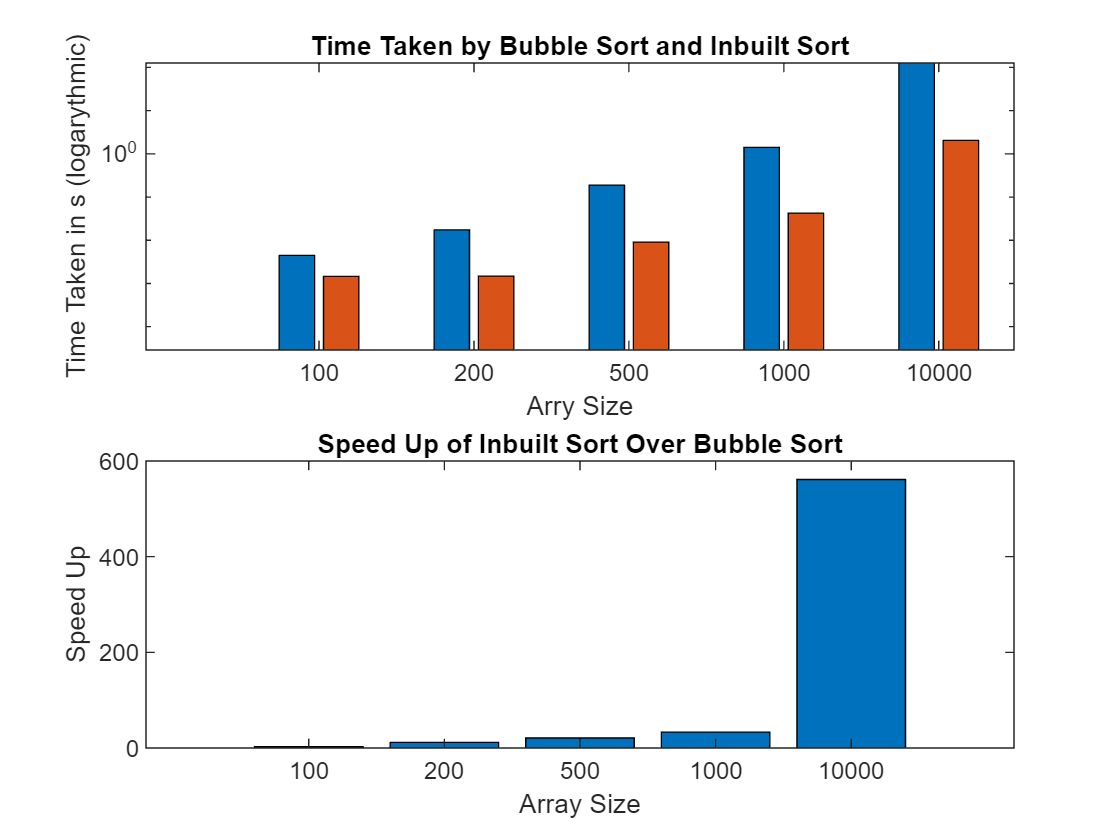

% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken(2:end ,2:3)));
% Add labels and title
xlabel('Arry Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Time Taken by Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

% Add a legend
legend('Bubble Sort Time', 'Inbuilt Sort Time')


% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Speed Up')
title('Speed Up of Inbuilt Sort Over Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

2.3.(c) Now for a bit of explicit parallelism (the MATLAB sort function tends to use implicit parallelism, i.e. you aren’t so aware of it being a parallel function). Use a parfor or spmd block to parallelize sorting of the columns of X. Test at least matrices of size 100, 5000 [15 marks]

% Initialize the cell array
testsizes = [100, 5000];
timetaken_par = cell(1+length(testsizes),4);
timetaken_par(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken_par(2:end,1) = num2cell(testsizes); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken_par
for i = 2:size(timetaken_par,1)
    % Call the timetest function with the value in the first column of the i-th row
    timeBubble = timebubble_parallelism(timetaken_par{i,1});
    timeInbuilt = timesort_parallelism(timetaken_par{i,1}); 
    timetaken_par{i,2} = timeBubble;
    timetaken_par{i,3} = timeInbuilt;
    disp(i)
    % Calculate speed up
    timetaken_par{i,4} = timeBubble/timeInbuilt;
end

    "Time tacken by the parallelism bubble sort function was 0.41001"



    "Time tacken by the sort function was 0.0004377"



     2



    "Time tacken by the parallelism bubble sort function was 1.9718"



    "Time tacken by the sort function was 0.45795"



     3




% Display the results
disp(timetaken_par)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.4100]}    {[         4.3770e-04]}    {[  936.7450]}
    {[  5000]}    {[            1.9718]}    {[             0.4580]}    {[    4.3056]}



Ploting bar graphs for this qustion 

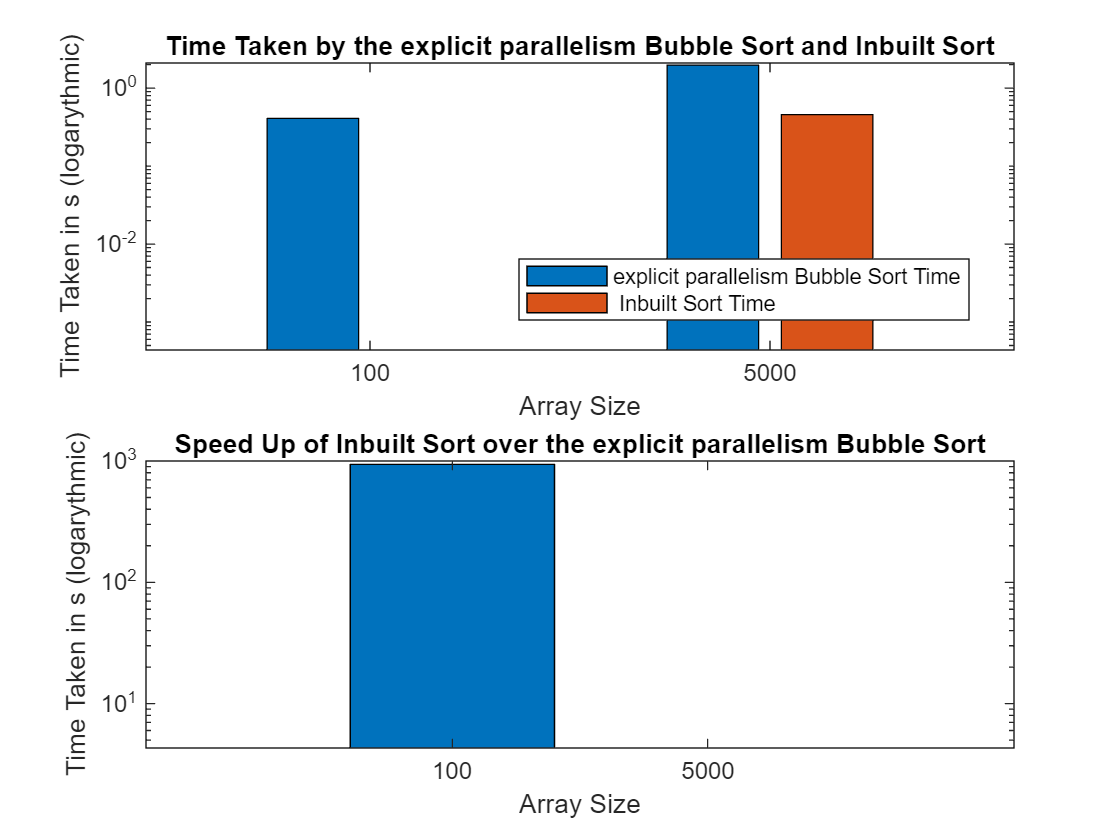


% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken_par(2:end ,2:3)));
% Add labels and title
xlabel('Array Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Time Taken by the explicit parallelism Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))

% Add a legend
legend('explicit parallelism Bubble Sort Time', ' Inbuilt Sort Time')


xlim([0.44 2.61])
ylim([0.00 2.10])
legend("Position", [0.4631,0.61953,0.40179,0.072619])

% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken_par(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Time Taken in s (logarythmic)')
set(gca, 'YScale', 'log')
title('Speed Up of Inbuilt Sort over the explicit parallelism Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken_par(2:end,1))

% destroy parallel tools
p.delete;

Parallel pool using the 'Processes' profile is shutting down.
